dataFolder = '/GEE_30m';
labelIDs = [0 1];
pixelLabelIDs = {0 1};
classes = ["no_label", "flood"];

imgDir = fullfile(pwd, dataFolder, '/train', 'images');
imds = imageDatastore(imgDir);

floodLabelSmoothThreshold = 0.3;
sigma = 4;
labelDir = fullfile(pwd, dataFolder, '/train', 'labels');
labelFcn = @(filename) customlabelreader(filename, floodLabelSmoothThreshold, sigma);
pxds = pixelLabelDatastore(labelDir, classes, pixelLabelIDs, "ReadFcn",labelFcn);

i = readimage(imds, 1);
c = readimage(pxds, 1);
i1 = normalize(i(:,:,1), 'range', [0 1]);
c1 = double(c);
b = labeloverlay(i1,c1,'ColorMap', [0.7 0.7 0.7; 0 0 1]);
imshow(b);

tbl = countEachLabel(pxds)

tbl = 2×3 table
        Name        PixelCount    ImagePixelCount
    ____________    __________    _______________

    {'no_label'}    3.3572e+07      3.5297e+07   
    {'flood'   }    1.7249e+06      3.5297e+07   


frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')
% imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
% classWeights = median(imageFreq) ./ imageFreq

inputTileSize = [128, 128, 2];
patchesPerImage = 50;
biasThreshold = 0.4;

augmenter = imageDataAugmenter("RandRotation",[-90, 90], ...
    "RandYTranslation", [-10 10], ...
    'RandXTranslation', [-10 10], ...
    "RandXReflection", true);
dsTrain = imbalanceRandomPatchExtractionDatastore(imds, pxds, inputTileSize(1:2), biasThreshold, 100, "PatchesPerImage", patchesPerImage, 'DataAugmentation', augmenter);
inputBatch = preview(dsTrain);
disp(inputBatch)

        InputImage        ResponsePixelLabelImage
    __________________    _______________________

    {128×128×2 double}     {128×128 categorical} 
    {128×128×2 double}     {128×128 categorical} 
    {128×128×2 double}     {128×128 categorical} 
    {128×128×2 double}     {128×128 categorical} 
    {128×128×2 double}     {128×128 categorical} 
    {128×128×2 double}     {128×128 categorical} 
    {128×128×2 double}     {128×128 categorical} 
    {128×128×2 double}     {128×128 categorical} 



showImageWithLabel(inputBatch)

valImgDir = fullfile(pwd, dataFolder, '/validate', 'images');
valImds = imageDatastore(valImgDir);
valLabelDir = fullfile(pwd, dataFolder, '/validate', 'labels');
valPxds = pixelLabelDatastore(valLabelDir, classes, pixelLabelIDs, 'ReadFcn',labelFcn);
dsValidate = imbalanceRandomPatchExtractionDatastore(imds, pxds, inputTileSize(1:2), biasThreshold, 100, "PatchesPerImage", patchesPerImage,'DataAugmentation', augmenter);

% pxLayer = dicePixelClassificationLayer('Name','dice-Pixel-Classification-Layer','Classes',tbl.Name);
% pxLayer = pixelClassificationLayer('Name','Pixel-Classification-Layer','Classes',tbl.Name);%,'ClassWeights',classWeights);
lgraph = createUnet(inputTileSize, numel(classes), pxLayer);
% lgraph = unetLayers(inputTileSize, numel(classes), "EncoderDepth", 4);
% lgraph = replaceLayer(lgraph, 'Segmentation-Layer', pxLayer);
disp(lgraph.Layers)

  46×1 Layer array with layers:

     1   'ImageInputLayer'                        Image Input                  128×128×2 images with 'zerocenter' normalization
     2   'Encoder-Section-1-Conv-1'               Convolution                  64 2×2×2 convolutions with stride [1  1] and padding 'same'
     3   'Encoder-Section-1-ReLU-1'               ReLU                         ReLU
     4   'Encoder-Section-1-Conv-2'               Convolution                  64 2×2×64 convolutions with stride [1  1] and padding 'same'
     5   'Encoder-Section-1-ReLU-2'               ReLU                         ReLU
     6   'Encoder-Section-1-MaxPool'              Max Pooling                  2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'Encoder-Section-2-Conv-1'               Convolution                  128 2×2×64 convolutions with stride [1  1] and padding 'same'
     8   'Encoder-Section-2-ReLU-1'

initialLearningRate = 0.01;
maxEpochs = 100;
minibatchSize = 4;
l2reg = 0.0001;

options = trainingOptions('sgdm',...
    'InitialLearnRate',initialLearningRate,...
    'ValidationData', dsValidate,...
    'ValidationFrequency', 100,...
    'Momentum',0.9,...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs,...
    'MiniBatchSize',minibatchSize,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropFactor', 0.1,...
    'GradientThreshold',6,...
    'LearnRateDropPeriod', 5,...
    'Shuffle','every-epoch',...
    'GradientThresholdMethod','l2norm',...
    'Plots','training-progress',...
    'VerboseFrequency',20,...
    "ExecutionEnvironment","gpu");
%     "CheckpointPath", strcat(pwd, dataFolder, '/checkpoint'));

doTraining = true;
if doTraining
    modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
    [net,info] = trainNetwork(dsTrain,lgraph,options);
%     save(['savedUnet-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net','options');
end

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:17 |       54.25% |       61.51% |       0.6030 |       0.5980 |          0.0100 |


|       1 |          20 |       00:00:22 |       46.33% |              |       0.5965 |              |          0.0100 |


|       1 |          40 |       00:00:26 |       51.28% |              |       0.5871 |              |          0.0100 |


|       1 |          60 |       00:00:31 |       55.18% |              |       0.5968 |              |          0.0100 |


|       1 |          80 |       00:00:35 |       99.87% |              |       0.4393 |              |          0.0100 |


|       1 |         100 |       00:00:55 |      100.00% |       61.50% |       0.2062 |       0.6467 |          0.0100 |


|       1 |         120 |       00:00:59 |       65.39% |              |       0.5783 |              |          0.0100 |


|       1 |         140 |       00:01:03 |       52.58% |              |       0.6173 |              |          0.0100 |


|       1 |         160 |       00:01:06 |       51.95% |              |       0.5959 |              |          0.0100 |


|       1 |         180 |       00:01:11 |       49.32% |              |       0.5875 |              |          0.0100 |


|       2 |         200 |       00:01:30 |       56.20% |       62.41% |       0.5962 |       0.5784 |          0.0100 |


|       2 |         220 |       00:01:34 |       39.54% |              |       0.6535 |              |          0.0100 |


|       2 |         240 |       00:01:38 |       41.17% |              |       0.6318 |              |          0.0100 |


|       2 |         260 |       00:01:43 |       51.80% |              |       0.5904 |              |          0.0100 |


|       2 |         280 |       00:01:48 |       59.54% |              |       0.5986 |              |          0.0100 |


|       2 |         300 |       00:02:07 |       57.49% |       62.96% |       0.6095 |       0.5897 |          0.0100 |


|       2 |         320 |       00:02:13 |       81.16% |              |       0.4254 |              |          0.0100 |


|       2 |         340 |       00:02:17 |       50.39% |              |       0.6657 |              |          0.0100 |


|       2 |         360 |       00:02:20 |       56.49% |              |       0.6114 |              |          0.0100 |


|       3 |         380 |       00:02:25 |       47.08% |              |       0.6473 |              |          0.0100 |


|       3 |         400 |       00:02:45 |       42.14% |       65.64% |       0.6440 |       0.5584 |          0.0100 |


|       3 |         420 |       00:02:49 |       47.40% |              |       0.6372 |              |          0.0100 |


|       3 |         440 |       00:02:54 |       69.74% |              |       0.5377 |              |          0.0100 |


|       3 |         457 |       00:02:58 |       53.35% |              |       0.6326 |              |          0.0100 |
|======================================================================================================================|


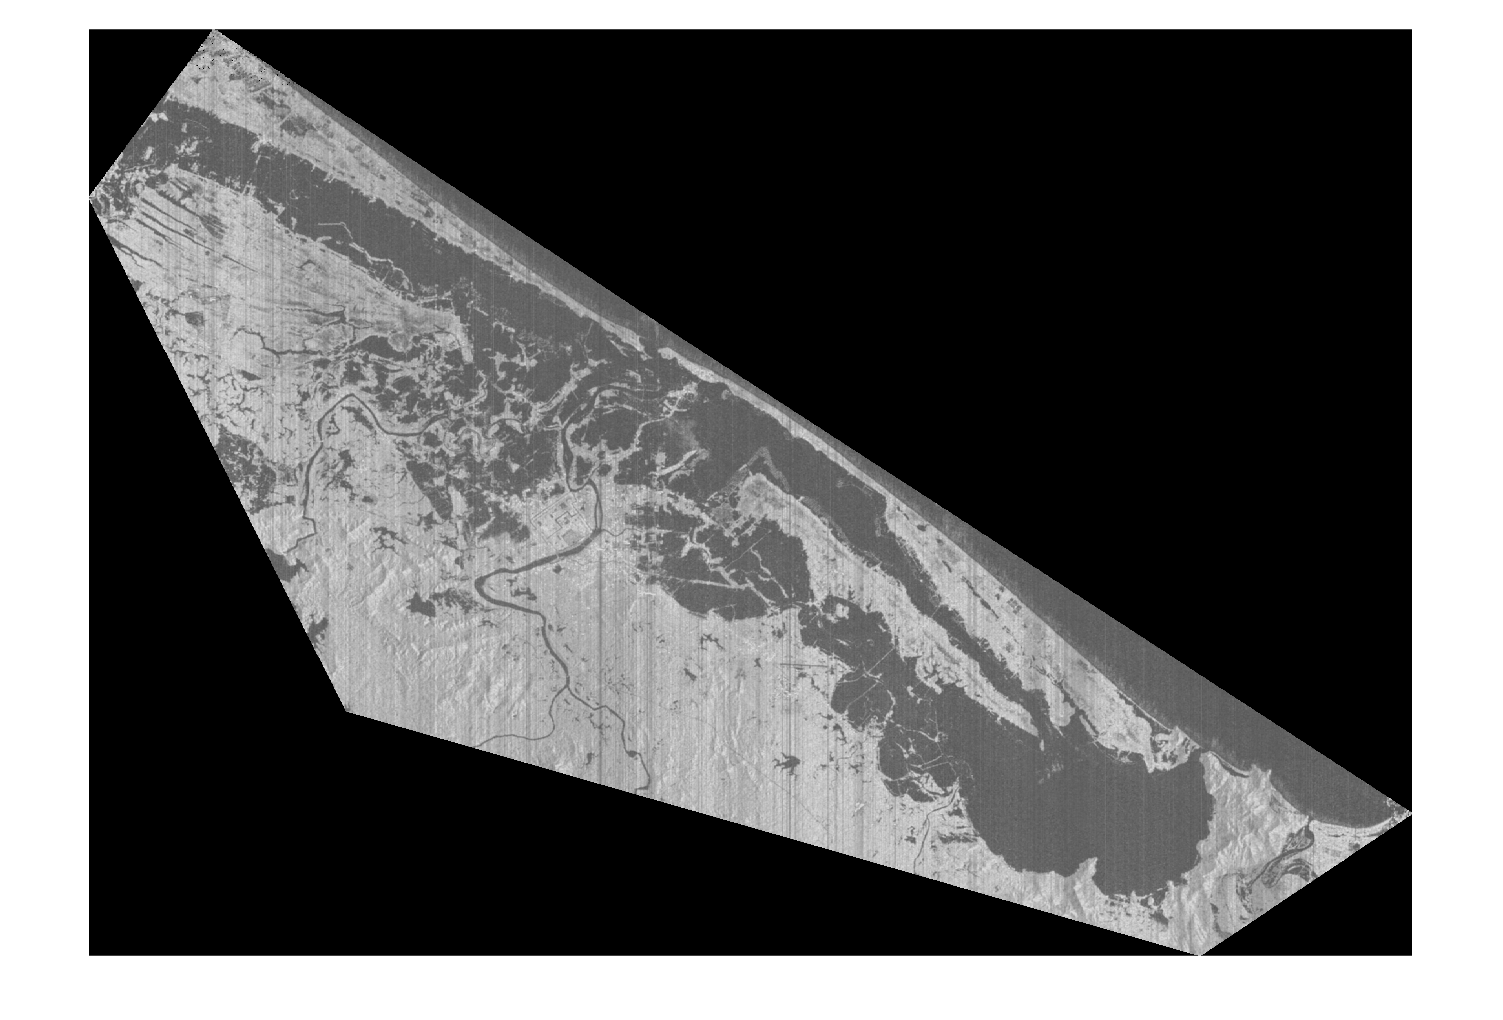

predictPatchSize = [1024 1024];
test_data = imread('C:\Do-an\GEE_30m\test\images\input_hue_1010.tif');
i2 = normalize(test_data(:,:,1), 'range', [0 1]);
% imshow(i2);
segmentedImage = segmentImage(test_data,net,predictPatchSize);
t1 = normalize(test_data(:,:,1), 'range', [0 1]);
s1 = double(segmentedImage);
b = labeloverlay(t1,s1,'ColorMap', [0.7 0.7 0.7; 0 0 1]);
imshow(b);

 unique(segmentedImage)

ans = uint8
1